# Numerical Solution to Poisson's Equation in Cartesian Coordinates Using Finite Difference Approximation 

                                                                                                                                                                                                                                                                                                                                                                            ***Kadir Mete Üstündağ***

##                                                                                             I. About the Method Finite Difference Approximation                                                                                     

    Finite difference is a numerical approximation to solution of partial differential equation. It can be a good way to solve nonlinear PDEs numerically since we may fail solving them analytically. In this report, I will implement finite difference method to solve Poisson's equation, obtain Potential and Electrical field. One can obtain following first order central difference derivative approximation at P by given curve.

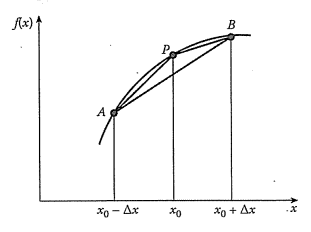                                                    

                                                                                                                       *Figure 1: Derivative approach                                                                                    Equation 1: First order derivative formula*

We can obtain second order form by applying first order equation twice:

     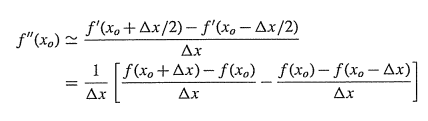                                               

                                                                                             * Equation 2: Apply first order central difference equation twice                                              Equation 3: Second order central difference derivative approxiation *

Then If we want to apply this equation for two parameters in order to obtain 2D PDE solution, we can use a scheme which can be seen in *Figure 5* to visualize the progress.            

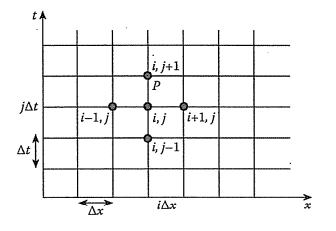

*Figure 2: Finite Difference Scheme with Two Independent Parameters*

And we can implement approximated equations to solve Laplacian numerically.

               

*Equation 4: Numerical Laplacian solution*

Since both $\textrm{∆}\mathrm{x}$ and $\textrm{∆t}$ are treated as differential length, I will assume that $\textrm{∆}\mathrm{x}$ = $\textrm{∆t}$ for simplicity.

        

*Equation 5: Numerical Laplacian solution simpler*

Since we get rid of differential operators after previous calculations, we can express desired equation with linear algebraic terms. Then equating this to the function f which is -k*pv/ε, we can get Poisson's equation. 

*Equation 6: Numerical nonhomogenous Laplacian solution in linear algebraic terms*

Here A is approximated Laplacian matrix and V is potential distribution. 

## II. Constructing the Code

Here I will construct the code which solves the Poisson's equation with using the linear algebraic equation. First I will set the N value which is the number of points between two integer points.

clc
clear
% N = point number between two integer
N = 100;
% set dl = approximate differential length
dx =  1/N;

Required inputs for f function which is nonhomogenous part of the Poisson's equation:

e = input("dielectric constant of the medium: ");
pv = input("charge distribution (give (N*N,1) matrix): ");
f = -pv/e;

I will first solve the Laplace's equation which is homogenous part, then I will implement nonhomogenous part to obtain complete solution. In order to do that, I will construct the A matrix which is approximated Laplacian operator.

% First solve the Laplace's equation with finite difference approximation
A_diag0 =  eye(N) * (-4 / dx^2);
A_diag0 = A_diag0 + diag(ones(N-1,1), 1) / dx^2;
A_diag0 = A_diag0 + diag(ones(N-1,1), -1) / dx^2;
A_diag1 = eye(N) / dx^2;
% I realised program slows down here because of the size of the matrix.
% Since there are so many 0 entries, using sparse is more efficient
A = sparse(N*N , N*N);

Setting central, upper and lower diagonal entries:

% central diagonal entries
for i = 1:N
    A((i-1)*N+1:(i-1)*N+N, (i-1)*N+1:(i-1)*N+N) = A_diag0; 
end 

% upper and lower diagonal entries
for i = 2:N
    A((i-2)*N+1:(i-2)*N+N, (i-1)*N+1:(i-1)*N+N) = A_diag1;
    A((i-1)*N+1:(i-1)*N+N, (i-2)*N+1:(i-2)*N+N) = A_diag1;
end

Here I will implement boundary conditions which are Dirichlet boundary conditions since we take some constant value as input.

% set boundary condition (Dirichlet boundary condition/some constant number)
V0x1 = input("V0x1, x axis lower boundary condition: ");
V0y1 = input("V0y1, y axis left hand side boundary condition: ");
V0x2 = input("V0x2, x axis upper boundary condition: ");
V0y2 = input("V0y2, y axis right hand side boundary condition: ");


% setting x axis lower boundary condition
for i=(N-1)*N+1:1:N*N
    V(i)=V0x1/dx^2;
end

% setting y axis left hand side boundary condition
for i=1:N:N*(N-1)+1
    V(i)=V0y1/dx^2;
end

% setting x axis upper boundary condition
for i=1:1:N
    V(i)=V0y2/dx^2;
end

% setting y axis right hand side boundary condition 
for i=N:N:(N*N)
    V(i)=V0x2/dx^2;
end

After applying boundary conditions, we can solve Poisson's equation using both homogenous and nonhomogenous part. Since we are dealing with linear algebra here, we can solve this problem with backslash operator and the solution gives the electric potential.

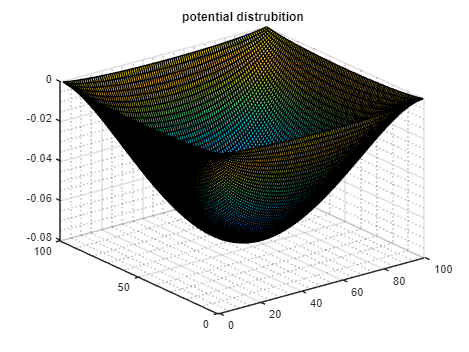

% finding potential
V = -A\f;
V = reshape(V, N, N);
surf(V)
grid minor
title("potential distrubition")

Since we have potential, we can use gradient function to obtain electrical field.

% finding electric field
figure;
x = linspace(0,1,(N));
y = x';
reshape(V.',1,[])

ans =    -0.0003   -0.0005   -0.0007   -0.0009   -0.0010   -0.0012   -0.0013   -0.0014   -0.0016   -0.0017   -0.0018   -0.0019   -0.0020   -0.0021   -0.0021   -0.0022   -0.0023   -0.0024   -0.0024   -0.0025   -0.0026   -0.0026   -0.0027   -0.0027   -0.0028   -0.0028   -0.0029   -0.0029   -0.0030   -0.0030   -0.0030   -0.0031   -0.0031   -0.0031   -0.0032   -0.0032   -0.0032   -0.0032   -0.0032   -0.0033   -0.0033   -0.0033   -0.0033   -0.0033   -0.0033   -0.0033   -0.0034   -0.0034   -0.0034   -0.0034


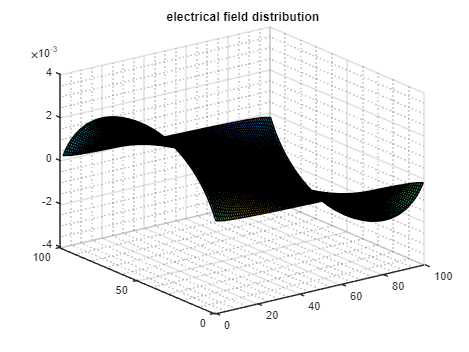

[EX,EY] = gradient(-V);
surf(EX,EY);
grid minor
title("electrical field distribution")

Then we can construct equipotential surfaces and electrical field lines.

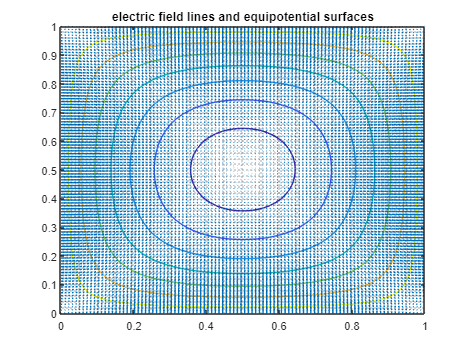

% electric field lines and equipotential surfaces
figure;
contour(x,y,V)
hold on
quiver(x,y,EX,EY)
grid minor
title("electric field lines and equipotential surfaces")

Some useful inputs:

% point charge at the center
% reshape(diag([zeros(1,49) 100000 zeros(1,50)]).',[],1)

% uniform charge distribution
% ones(N*N,1)